clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

FPs = obj.MixedFP;
beh = obj.BehavTable;

session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");


## Hold duration and reaction time

hd_control = cell(3, 2);
hd_chemo = cell(3, 2);
rt_control = cell(3, 2);
rt_chemo = cell(3, 2);

for fp = 1:3
    for p = 1:2
        hd_control{fp, p} = obj.HDSortedControl{fp, p};
        hd_chemo{fp, p} = obj.HDSortedChemo{fp, p};

        rt_control{fp, p} = hd_control{fp, p} - FPs(fp);
        rt_chemo{fp, p} = hd_chemo{fp, p} - FPs(fp);

        rt_control{fp, p} = rt_control{fp, p}(rt_control{fp, p}>=0);
        rt_chemo{fp, p} = rt_chemo{fp, p}(rt_chemo{fp, p}>=0);
    end
end


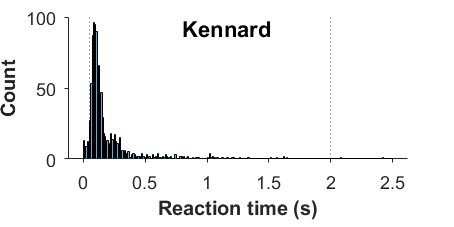

rt_lower = .05;
rt_upper = 2;

fig_rt_hist = figure(30); clf(fig_rt_hist);
set(fig_rt_hist, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 4], 'Color', 'w', 'toolbar', 'none');

ax_rt_hist = axes(fig_rt_hist, 'NextPlot', 'add', 'Units', 'centimeters', 'Position', [1.2 1.2 6 2.5], 'FontSize', 9, 'TickDir', 'out');

histogram(ax_rt_hist, [cell2mat(rt_control(:)); cell2mat(rt_chemo(:))], 'BinEdges', 0:0.01:2.5, 'LineWidth', .1);
xline(ax_rt_hist, [rt_lower rt_upper], 'LineWidth', .5, 'LineStyle', ':', 'Color', 'k');

ax_rt_hist.XLabel.String = "Reaction time (s)";
ax_rt_hist.XLabel.FontWeight = "bold";
ax_rt_hist.YLabel.String = "Count";
ax_rt_hist.YLabel.FontWeight = "bold";

set_fig_title(fig_rt_hist, obj.Subject, 'FontSize', 11);

fig_name = sprintf("Test_%s_RT_trim_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_rt_hist, fig_path, 'Resolution', 600);

trim_rt = @(x) x(x>=rt_lower & x<=rt_upper);
rt_control = cellfun(@(x) trim_rt(x), rt_control, 'UniformOutput', false);
rt_chemo = cellfun(@(x) trim_rt(x), rt_chemo, 'UniformOutput', false);


hd_bins = 0:0.001:3;
band_width = 0.05;
alpha_boot = 0.05;

alpha_boot = 0.0500

n_boot = 1000;

kde_hd_pdf = @(x) ksdensity(x, hd_bins, 'Function', 'pdf', 'Bandwidth', band_width);
boot_hd_pdf = @(x) bootci(n_boot, {kde_hd_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);

hd_pd_control = cellfun(@(x) kde_hd_pdf(x), hd_control, 'UniformOutput', false);
hd_pd_chemo = cellfun(@(x) kde_hd_pdf(x), hd_chemo, 'UniformOutput', false);

hd_pd_ci_control = cellfun(@(x) boot_hd_pdf(x), hd_control, 'UniformOutput', false);
hd_pd_ci_chemo = cellfun(@(x) boot_hd_pdf(x), hd_chemo, 'UniformOutput', false);

hd_pd_max = max(max(cellfun(@(x1, x2) max([x1(2,:) x2(2,:)]), hd_pd_ci_control, hd_pd_ci_chemo)));
hd_pd_ylim = .5 * (ceil(hd_pd_max) + round(hd_pd_max));


rt_bins = 0:0.001:rt_upper;

kde_rt_pdf = @(x) ksdensity(x, rt_bins, 'Function', 'pdf', 'Bandwidth', band_width);
boot_rt_pdf = @(x) bootci(n_boot, {kde_rt_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);

rt_pd_control = cellfun(@(x) kde_rt_pdf(x), rt_control, 'UniformOutput', false);
rt_pd_chemo = cellfun(@(x) kde_rt_pdf(x), rt_chemo, 'UniformOutput', false);

rt_pd_ci_control = cellfun(@(x) boot_rt_pdf(x), rt_control, 'UniformOutput', false);
rt_pd_ci_chemo = cellfun(@(x) boot_rt_pdf(x), rt_chemo, 'UniformOutput', false);

rt_pd_max = max(max(cellfun(@(x1, x2) max([x1(2,:) x2(2,:)]), rt_pd_ci_control, rt_pd_ci_chemo)));
rt_pd_ylim = .5 * (ceil(rt_pd_max) + round(rt_pd_max));


[~, hd_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), hd_control, hd_chemo);
hd_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), hd_control, hd_chemo);

[~, rt_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), rt_control, rt_chemo);
rt_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), rt_control, rt_chemo);


hd_categories = [0 .25 .5 2];
rt_categories = [.25 .5 2];

hd_p_chi2 = zeros(3, 2);
rt_p_chi2 = zeros(3, 2);
hd_p_chi2_sub = cell(3, 2);
rt_p_chi2_sub = cell(3, 2);
for fp = 1:3
    for p = 1:2
        [hd_p_chi2(fp, p), ~, hd_p_chi2_sub{fp, p}] = Chi2Test_Distr({hd_control{fp, p}-FPs(fp), hd_chemo{fp, p}-FPs(fp)}, hd_categories);
        [rt_p_chi2(fp, p), ~, rt_p_chi2_sub{fp, p}] = Chi2Test_Distr({rt_control{fp, p}, rt_chemo{fp, p}}, rt_categories);
    end
end

alpha = [.05 .01 .001];
alpha_hd = alpha ./ length(hd_categories);
alpha_rt = alpha ./ length(rt_categories);

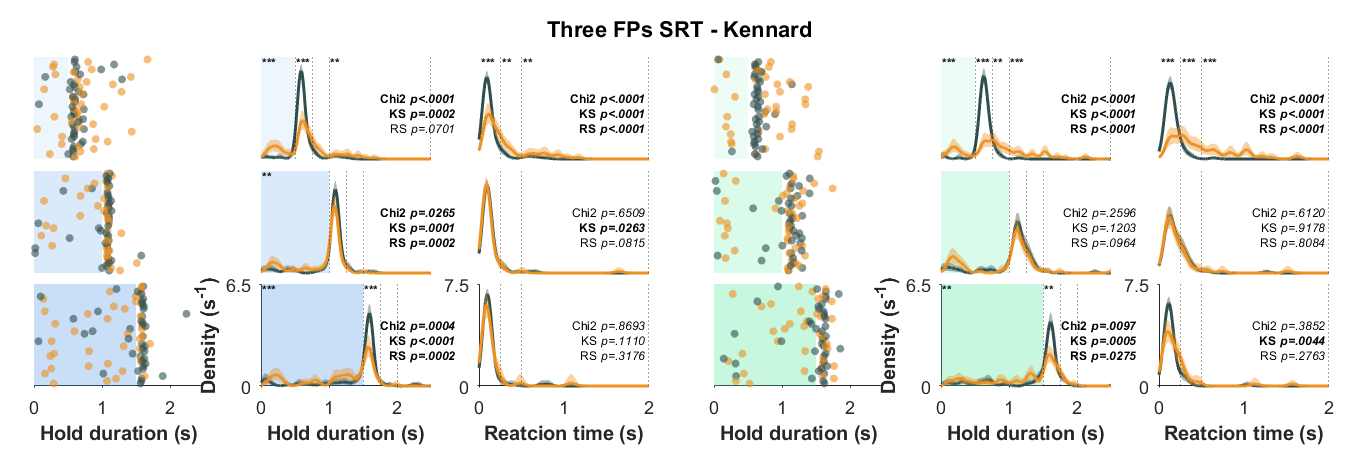

n_show = 40;

fig_srt = figure(31); clf(fig_srt);
set(fig_srt, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 24 8], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_srt, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_hd_s = cell(3,2);
ax_hd_pd = cell(3,2);
ax_rt_pd = cell(3,2);

ax_w = 3; ax_h = 1.8;
ax_w_sep = 1; ax_h_sep = .2;

for fp = 1:3
    for p = 1:2
    
        hd_this = [hd_control{fp, p}(randperm(length(hd_control{fp, p}), n_show)); 
            hd_chemo{fp, p}(randperm(length(hd_chemo{fp, p}), n_show))];
        c_this = [repmat(GPSColor.Control, n_show, 1); 
            repmat(GPSColor.Treat, n_show, 1)];
        id_this = [1:n_show 1:n_show]';
        perm_this = randperm(2*n_show);

        % Hold duration scatter
        ax_hd_s{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.6+(p-1)*3*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YColor', 'none');
        fill(ax_hd_s{fp, p}, [0 FPs(fp) FPs(fp) 0], [0 0 n_show+1 n_show+1], 'r', ...
            'EdgeColor', 'none', 'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', 0.3*FPs(fp)/max(FPs))
        scatter(ax_hd_s{fp, p}, hd_this(perm_this), id_this(perm_this), 16, c_this(perm_this, :), 'fill', ...
            'MarkerFaceAlpha', .6, 'MarkerEdgeAlpha', .6);
        set(ax_hd_s{fp, p}, 'XLim', [0 2.5], 'YLim', [0 n_show+1], 'YTickLabel', []);
        switch fp
            case 3
                ax_hd_s{fp, p}.XLabel.String = "Hold duration (s)";
                ax_hd_s{fp, p}.XLabel.FontWeight = "bold";
            otherwise
                set(ax_hd_s{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        % Hold duration PDF
        ax_hd_pd{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.6+(3*p-2)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        xline(ax_hd_pd{fp, p}, FPs(fp)+hd_categories, 'LineWidth', .5, 'Color', 'k', 'LineStyle', ':');
        fill(ax_hd_pd{fp, p}, [0 FPs(fp) FPs(fp) 0], [0 0 hd_pd_ylim hd_pd_ylim], 'r', ...
            'EdgeColor', 'none', 'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', 0.3*FPs(fp)/max(FPs));
        fill(ax_hd_pd{fp, p}, [hd_bins flip(hd_bins)], [hd_pd_ci_control{fp, p}(1,:) flip(hd_pd_ci_control{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_hd_pd{fp, p}, hd_bins, hd_pd_control{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        fill(ax_hd_pd{fp, p}, [hd_bins flip(hd_bins)], [hd_pd_ci_chemo{fp, p}(1,:) flip(hd_pd_ci_chemo{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_hd_pd{fp, p}, hd_bins, hd_pd_chemo{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);

        set(ax_hd_pd{fp, p}, 'XLim', [0 2.5], 'YLim', [0 hd_pd_ylim], 'YTick', [0 hd_pd_ylim]);
        switch fp
            case 3
                ax_hd_pd{fp, p}.XLabel.String = "Hold duration (s)";
                ax_hd_pd{fp, p}.XLabel.FontWeight = "bold";
                ax_hd_pd{fp, p}.YLabel.String = "Density (s^{-1})";
                ax_hd_pd{fp, p}.YLabel.FontWeight = "bold";
            otherwise
                set(ax_hd_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        % Significance
        if hd_p_chi2(fp, p)<.0001
            text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .6*ax_hd_pd{fp, p}.YLim(2), "Chi2 \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("Chi2 \\it{p}=%.4f", hd_p_chi2(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if hd_p_chi2(fp, p)<.05
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .6*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .6*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        hd_edges = [0 FPs(fp)+hd_categories];
        if hd_p_chi2(fp, p)<.05
            for c = 1:length(hd_categories)
                if hd_p_chi2_sub{fp, p}(c) < alpha_hd(3)
                    text(ax_hd_pd{fp, p}, .02+hd_edges(c), .95*ax_hd_pd{fp, p}.YLim(2), '***', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                elseif hd_p_chi2_sub{fp, p}(c) < alpha_hd(2)
                    text(ax_hd_pd{fp, p}, .02+hd_edges(c), .95*ax_hd_pd{fp, p}.YLim(2), '**', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                elseif hd_p_chi2_sub{fp, p}(c) < alpha_hd(1)
                    text(ax_hd_pd{fp, p}, .02+hd_edges(c), .95*ax_hd_pd{fp, p}.YLim(2), '**', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                end
            end
        end

        if hd_p_KS(fp, p)<.0001
            text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .45*ax_hd_pd{fp, p}.YLim(2), "KS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("KS \\it{p}=%.4f", hd_p_KS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if hd_p_KS(fp, p)<.05
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .45*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .45*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        if hd_p_RS(fp, p)<.0001
            text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .3*ax_hd_pd{fp, p}.YLim(2), "RS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("RS \\it{p}=%.4f", hd_p_RS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if hd_p_RS(fp, p)<.05
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .3*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_hd_pd{fp, p}, 1.15*ax_hd_pd{fp, p}.XLim(2), .3*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end

        % Reaction time PDF
        ax_rt_pd{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.45+(3*p-1)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        xline(ax_rt_pd{fp, p}, rt_categories, 'LineWidth', .5, 'Color', 'k', 'LineStyle', ':');
        fill(ax_rt_pd{fp, p}, [rt_bins flip(rt_bins)], [rt_pd_ci_control{fp, p}(1,:) flip(rt_pd_ci_control{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_rt_pd{fp, p}, rt_bins, rt_pd_control{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        fill(ax_rt_pd{fp, p}, [rt_bins flip(rt_bins)], [rt_pd_ci_chemo{fp, p}(1,:) flip(rt_pd_ci_chemo{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_rt_pd{fp, p}, rt_bins, rt_pd_chemo{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);

        set(ax_rt_pd{fp, p}, 'XLim', [0 rt_upper], 'YLim', [0 rt_pd_ylim], 'YTick', [0 rt_pd_ylim]);
        switch fp
            case 3
                ax_rt_pd{fp, p}.XLabel.String = "Reatcion time (s)";
                ax_rt_pd{fp, p}.XLabel.FontWeight = "bold";
            otherwise
                set(ax_rt_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        if rt_p_chi2(fp, p)<.0001
            text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .6*ax_rt_pd{fp, p}.YLim(2), "Chi2 \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("Chi2 \\it{p}=%.4f", rt_p_chi2(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if rt_p_chi2(fp, p)<.05
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .6*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .6*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        rt_edges = [0 rt_categories];
        if rt_p_chi2(fp, p)<.05
            for c = 1:length(rt_categories)
                if rt_p_chi2_sub{fp, p}(c) < alpha_hd(3)
                    text(ax_rt_pd{fp, p}, .02+rt_edges(c), .95*ax_rt_pd{fp, p}.YLim(2), '***', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                elseif rt_p_chi2_sub{fp, p}(c) < alpha_hd(2)
                    text(ax_rt_pd{fp, p}, .02+rt_edges(c), .95*ax_rt_pd{fp, p}.YLim(2), '**', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                elseif rt_p_chi2_sub{fp, p}(c) < alpha_hd(1)
                    text(ax_rt_pd{fp, p}, .02+rt_edges(c), .95*ax_rt_pd{fp, p}.YLim(2), '**', ...
                        'HorizontalAlignment', 'left', 'FontSize', 6, 'FontWeight', 'bold');
                end
            end
        end

        if rt_p_KS(fp, p)<.0001
            text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .45*ax_rt_pd{fp, p}.YLim(2), "KS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("KS \\it{p}=%.4f", rt_p_KS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if rt_p_KS(fp, p)<.05
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .45*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .45*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        if rt_p_RS(fp, p)<.0001
            text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .3*ax_rt_pd{fp, p}.YLim(2), "RS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("RS \\it{p}=%.4f", rt_p_RS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if rt_p_RS(fp, p)<.05
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .3*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_rt_pd{fp, p}, .98*ax_rt_pd{fp, p}.XLim(2), .3*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
    end
end

fig_name = sprintf("Test_%s_Distr_SRT_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_srt, fig_path, 'Resolution', 600);

## Movement time

mt_lower = 0.2;
mt_upper = 1;

mt_control = cell(3, 2);
mt_chemo = cell(3, 2);

for fp = 1:3
    for p = 1:2
        mt_control{fp, p} = beh.MovementTime(beh.Label=="Control" & beh.FP==FPs(fp) & beh.PortChosen==p);
        mt_chemo{fp, p} = beh.MovementTime(beh.Label=="Chemo" & beh.FP==FPs(fp) & beh.PortChosen==p);

        mt_control{fp, p} = mt_control{fp, p}(mt_control{fp, p}<mt_upper);
        mt_chemo{fp, p} = mt_chemo{fp, p}(mt_chemo{fp, p}<mt_upper);
    end
end


mt_bins = 0:0.001:1;
band_width = 0.05;
n_boot = 1000;

kde_mt_pdf = @(x) ksdensity(x, mt_bins, 'Function', 'pdf', 'Bandwidth', band_width);
boot_mt_pdf = @(x) bootci(n_boot, {kde_mt_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);

mt_pd_control = cellfun(@(x) kde_mt_pdf(x), mt_control, 'UniformOutput', false);
mt_pd_chemo = cellfun(@(x) kde_mt_pdf(x), mt_chemo, 'UniformOutput', false);

mt_pd_ci_control = cellfun(@(x) boot_mt_pdf(x), mt_control, 'UniformOutput', false);
mt_pd_ci_chemo = cellfun(@(x) boot_mt_pdf(x), mt_chemo, 'UniformOutput', false);

mt_pd_max = max(max(cellfun(@(x1, x2) max([x1(2,:) x2(2,:)]), mt_pd_ci_control, mt_pd_ci_chemo)));
mt_pd_ylim = .5 * (ceil(mt_pd_max) + round(mt_pd_max));


[~, mt_p_t] = cellfun(@(x1, x2) ttest2(x1, x2), mt_control, mt_pd_chemo);
[~, mt_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), mt_control, mt_pd_chemo);
mt_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), mt_control, mt_pd_chemo);


mt_categories = [.5 1];

mt_p_chi2 = zeros(3, 2);
mt_p_chi2_sub = cell(3, 2);
for fp = 1:3
    for p = 1:2
        mt_p_chi2(fp, p) = Chi2Test_Distr({mt_control{fp, p}, mt_chemo{fp, p}}, mt_categories);
    end
end


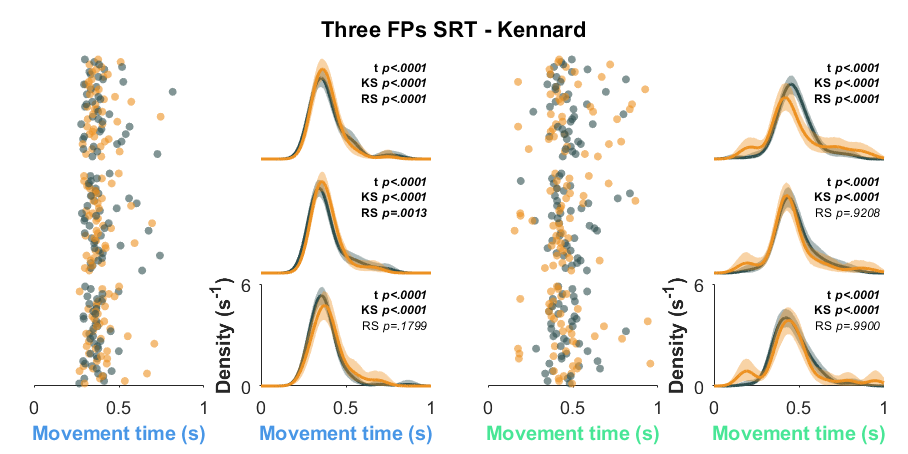

ntrial_min = min(min(cellfun(@(x1, x2) min([length(x1) length(x2)]), mt_control, mt_chemo)));
n_show = min([40 ntrial_min]);

fig_mt = figure(32); clf(fig_mt);
set(fig_mt, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 16 8], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_mt, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_mt_s = cell(3,2);
ax_mt_pd = cell(3,2);

ax_w = 3; ax_h = 1.8;
ax_w_sep = 1; ax_h_sep = .2;

for fp = 1:3
    for p = 1:2

        mt_this = [mt_control{fp, p}(randperm(length(mt_control{fp, p}), n_show));
            mt_chemo{fp, p}(randperm(length(mt_chemo{fp, p}), n_show))];
        c_this = [repmat(GPSColor.Control, n_show, 1);
            repmat(GPSColor.Treat, n_show, 1)];
        id_this = [1:n_show 1:n_show]';
        perm_this = randperm(2*n_show);

        % Hold duration scatter
        ax_mt_s{fp, p} = axes(fig_mt, "Units", "centimeters", "Position", [.6+(p-1)*2*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YColor', 'none');
        scatter(ax_mt_s{fp, p}, mt_this(perm_this), id_this(perm_this), 16, c_this(perm_this, :), 'fill', ...
            'MarkerFaceAlpha', .6, 'MarkerEdgeAlpha', .6);
        set(ax_mt_s{fp, p}, 'XLim', [0 1], 'YLim', [0 n_show+1], 'YTickLabel', []);
        switch fp
            case 3
                ax_mt_s{fp, p}.XLabel.String = "Movement time (s)";
                ax_mt_s{fp, p}.XLabel.FontWeight = "bold";
                ax_mt_s{fp, p}.XLabel.Color = GPSColor.("Port"+obj.Ports(p));
            otherwise
                set(ax_mt_s{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        % Hold duration PDF
        ax_mt_pd{fp, p} = axes(fig_mt, "Units", "centimeters", "Position", [.6+(2*p-1)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        %         xline(ax_mt_pd{fp, p}, mt_categories, 'LineWidth', .5, 'Color', 'k', 'LineStyle', ':');
        fill(ax_mt_pd{fp, p}, [mt_bins flip(mt_bins)], [mt_pd_ci_control{fp, p}(1,:) flip(mt_pd_ci_control{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_mt_pd{fp, p}, mt_bins, mt_pd_control{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        fill(ax_mt_pd{fp, p}, [mt_bins flip(mt_bins)], [mt_pd_ci_chemo{fp, p}(1,:) flip(mt_pd_ci_chemo{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax_mt_pd{fp, p}, mt_bins, mt_pd_chemo{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);

        set(ax_mt_pd{fp, p}, 'XLim', [0 1], 'YLim', [0 mt_pd_ylim], 'YTick', [0 mt_pd_ylim]);
        switch fp
            case 3
                ax_mt_pd{fp, p}.XLabel.String = "Movement time (s)";
                ax_mt_pd{fp, p}.XLabel.FontWeight = "bold";
                ax_mt_pd{fp, p}.YLabel.String = "Density (s^{-1})";
                ax_mt_pd{fp, p}.YLabel.FontWeight = "bold";
                ax_mt_pd{fp, p}.XLabel.Color = GPSColor.("Port"+obj.Ports(p));
            otherwise
                set(ax_mt_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        % Significance
        if mt_p_t(fp, p)<.0001
            text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .9*ax_mt_pd{fp, p}.YLim(2), "t \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("t \\it{p}=%.4f", mt_p_t(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if mt_p_t(fp, p)<.05
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .9*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .9*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        if mt_p_KS(fp, p)<.0001
            text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .75*ax_mt_pd{fp, p}.YLim(2), "KS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("KS \\it{p}=%.4f", mt_p_KS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if mt_p_KS(fp, p)<.05
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .75*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .75*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
        if mt_p_RS(fp, p)<.0001
            text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .6*ax_mt_pd{fp, p}.YLim(2), "RS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
        else
            p_str = sprintf("RS \\it{p}=%.4f", mt_p_RS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            if mt_p_RS(fp, p)<.05
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .6*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'bold');
            else
                text(ax_mt_pd{fp, p}, .98*ax_mt_pd{fp, p}.XLim(2), .6*ax_mt_pd{fp, p}.YLim(2), p_str, ...
                    'HorizontalAlignment', 'right', 'FontSize', 6, 'FontWeight', 'normal');
            end
        end
    end
end

fig_name = sprintf("Test_%s_Distr_MT_SRT_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_mt, fig_path, 'Resolution', 600);